# **Sistemi dinamici - Solver ODE**

`MATLAB` implementa vari solver numerici per vari tipi di problemi. Quello che useremo qui si chiama `ode45`. Per saperne di più e verificare le alternative suggeriamo il solito protocollo

help ode45

 ode45 - Solve nonstiff differential equations — medium order method
    This MATLAB function, where tspan = [t0 tf], integrates the system of
    differential equations y'=f(t,y) from t0 to tf with initial conditions
    y0.

    Syntax
      [t,y] = ode45(odefun,tspan,y0)
      [t,y] = ode45(odefun,tspan,y0,options)
      [t,y,te,ye,ie] = ode45(odefun,tspan,y0,options)
      sol = ode45(___)

    Input Arguments
      odefun - Functions to solve
        function handle
      tspan - Interval of integration
        vector
      y0 - Initial conditions
        vector
      <a h

doc ode45
close all
clear all

## Un esempio: oscillatore armonico smorzato

Verifichiamo la sintassi di base. Uno scillatore armonico smorzato con massa $m$, costante elastica $k$ e coefficiente di attrito $\gamma$: l'evoluzione della coordinata $x$ può essere descritto da una ODE di secondo grado

        $m\ddot{x} =-kx-m\gamma \dot{x}$.

Non sorprenderà nessuno se diciamo che `ode45` risolve solo equazioni di grado primo, dato che possiamo sempre ricondurci a quel caso

        
$$\begin{array}{l}
\dot{x} =v\\
\dot{v} =-\omega_0^2 x-\gamma v
\end{array}$$


dove $\omega_0^2 =k/m$.

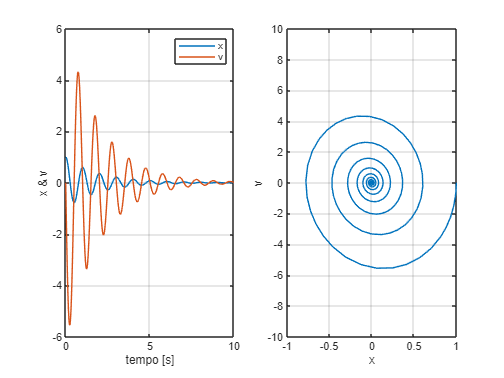

% Parametri
f0     = 1;
omega0 = 2*pi*f0;
gamma  = 1;
t0     = 0;
durata = 10;
x0     = 1;
v0     = 0;

% Soluzione numerica
% 1. Come definire una funzione a più componenti. Qui x(1) gioca il ruolo
% della posizione mentre x(2) quello della velocità
ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma*xv(2)];
% 2. Soluzione numerica usando ode45
[tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
xx = xv(:,1);
vv = xv(:,2);

% Plot del risultato
figure(1);
subplot(1,2,1);
plot(tt,[xx vv]);
legend("x","v");
grid on;
xlabel('tempo [s]');
ylabel('x & v');
subplot(1,2,2);
plot(xx,vv);
grid on;
xlabel('x');
ylabel('v');
axis([-1 1,-10,10]);

## Oscillatore di Duffing "standard"

L'equazione completa dell'oscillatore di Duffing consiste in un oscillatore armonico forzato e smorzato più un'espansione della costante elastica al second'ordine che produce un termine che va con il displacement al cubo.  

        
$$m\ddot{x} +m\gamma \dot{x} +k_1 x+k_3 x^3 =F\left(t\right)$$


dove $x$ è la posizione, $m$ la massa, $\gamma \;$il termine di smorzamento,$F\left(t\right)$ la forzante, $k_{1\;}$la costante elastica lineare e $k_3$ il termine di Duffing. Può essere costruttivo studiare come la dinamica dell'oscillatore armonico forzato e smorzato diventi gradualmente nonlineare introducendo il termine di Duffing.

### **Oscillatore armonico forzato e smorzato**

Partiamo quindi dall'esempio di cui sopra, aggiungendo una forzante semplice della forma $\textrm{Asin}\left(\omega t\right)$.

Vediamo inizialmente il caso di forzante risonante con la frequenza naturale dell'oscillatore

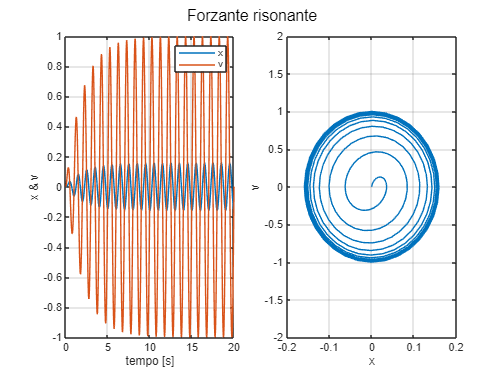

% Parametri
f0     = 1;
omega0 = 2*pi*f0;
gamma  = 1;
A = 1;
omegaD = 2*pi*f0; % Forzante con frequenza uguale alla frequenza naturale
t0     = 0;
durata = 20;
x0     = 0;
v0     = 0; % Cambiamo anche le condizioni iniziali e partiamo
% con un oscillatore fermo in posizione x = 0

% Soluzione numerica
ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma*xv(2)+A*sin(omegaD*t)];
% 2. Soluzione numerica usando ode45
[tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
xx = xv(:,1);
vv = xv(:,2);

% Plot del risultato
figure(2);
subplot(1,2,1);
plot(tt,[xx vv]);
legend("x","v");
grid on;
ylim([-1 1])
xlabel('tempo [s]');
ylabel('x & v');
subplot(1,2,2);
plot(xx,vv);
grid on;
xlim([-0.2 0.2])
ylim([-2 2])
xlabel('x');
ylabel('v');
sgtitle('Forzante risonante')

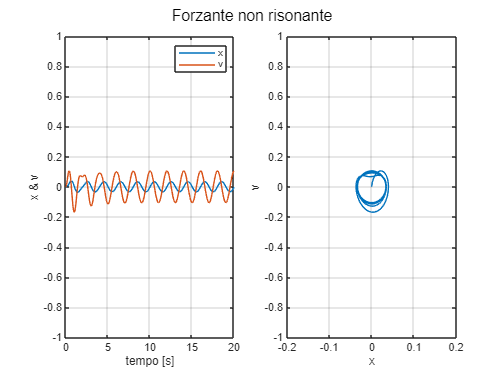

% Parametri
f0     = 1;
omega0 = 2*pi*f0;
gamma  = 1;
A = 1;
omegaD = 2*pi*f0/2; % Forzante con frequenza metà della frequenza naturale
t0     = 0;
durata = 20;
x0     = 0;
v0     = 0; % Cambiamo anche le condizioni iniziali e partiamo
% con un oscillatore fermo in posizione x = 0

% Soluzione numerica
ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma*xv(2)+A*sin(omegaD*t)];
% 2. Soluzione numerica usando ode45
[tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
xx = xv(:,1);
vv = xv(:,2);

% Plot del risultato
figure(3);
subplot(1,2,1);
plot(tt,[xx vv]);
legend("x","v");
grid on;
ylim([-1 1])
xlabel('tempo [s]');
ylabel('x & v');
subplot(1,2,2);
plot(xx,vv);
grid on;
xlim([-0.2 0.2])
ylim([-1 1])
xlabel('x');
ylabel('v');
sgtitle('Forzante non risonante')

E' abbastanza chiaro che l'ampiezza di oscillazione nel caso non risonante sia significativamente ridotta. Volendo essere più quantitativi, possiamo effettuare una "spazzata" della frequenza della forzante e registrare la massima ampiezza di oscillazione ottenuta, per esempio valutando la differenza tra massimo e minimo della curva $x\left(t\right)$al raggiungimento dello stato stazionario, quindi per tempi grandi.

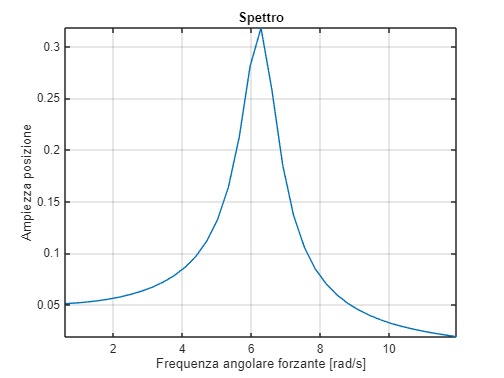

% Parametri
clearvars
f0     = 1;
omega0 = 2*pi*f0;
gamma  = 1;
A = 1;
omegaD = 2*pi*[0.1:0.05:1.9]; % Range di frequenze della forzante
t0     = 0;
durata = 20;
x0     = 0;
v0     = 0; % Cambiamo anche le condizioni iniziali e partiamo
% con un oscillatore fermo in posizione x = 0

for j=1:length(omegaD)
    % Soluzione numerica
    ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma*xv(2)+A*sin(omegaD(j)*t)];
    % 2. Soluzione numerica usando ode45
    [tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
    xx = xv(:,1);
    vv = xv(:,2);
    % Valutiamo l'ampiezza della posizione negli ultimi 150 punti della
    % scala temporale
    Amp(j) = max(xx(end-150:end)) - min(xx(end-150:end));
end

% Plot del risultato
figure(4);
plot(omegaD,Amp);
grid on;
axis tight
xlabel('Frequenza angolare forzante [rad/s]');
ylabel('Ampiezza posizione');
title('Spettro')

Possiamo notare come la curva sia una Lorentziana ragionevolmente simmetrica in regime di **underdamping**. Difatti la forma della curva dipende da quanto l'oscillatore sia smorzato. Proviamo adesso a risolvere lo stesso problema considerando tre diversi smorzamenti, cioè con smorzamento molto minore, molto maggiore o uguale alla frequenza naturale dell'oscillatore (quest'ultimo è il caso appena visto e prende il nome di *smorzamento critico*).

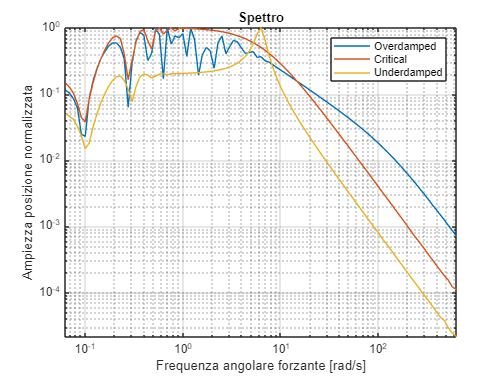

% Parametri
clearvars
f0     = 1;
omega0 = 2*pi*f0;
% Critico era mi sa gamma = omega0/2
gamma  = 4*pi*[10,1,0.1]; % Range di smorzamenti
A = 1;
omegaD = 2*pi*logspace(-2,2,101); % Range di frequenze della forzante
t0     = 0;
durata = 20;
x0     = 0;
v0     = 0; % Cambiamo anche le condizioni iniziali e partiamo
% con un oscillatore fermo in posizione x = 0

figure(5);
for js=1:length(gamma)
    for j=1:length(omegaD)
        % Soluzione numerica
        ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma(js)*xv(2)+A*sin(omegaD(j)*t)];
        % 2. Soluzione numerica usando ode45
        [tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
        xx = xv(:,1);
        vv = xv(:,2);
        % Valutiamo l'ampiezza della posizione negli ultimi 150 punti della
        % scala temporale
        Amp(j) = max(xx(end-150:end)) - min(xx(end-150:end));
    end

    % Plot del risultato
    loglog(omegaD,Amp/max(Amp));
    hold on
    grid on;
    axis tight
    xlabel('Frequenza angolare forzante [rad/s]');
    ylabel('Ampiezza posizione normalizzata');
    title('Spettro')
end
legend('Overdamped','Critical','Underdamped')

**Oscillatore armonico forzato e smorzato**

Vediamo quindi il caso dell'oscillatore di Duffing completo considerando separatamente $k_{3\;} >0$ e $k_{3\;} <0$. Modificheremo il codice con due piccole considerazioni aggiuntive:

- Per ragioni di convergenza numerica, ci spostiamo a frequenze naturali un po' più grandi per evitare la regione intorno a f = 0.

- E' conveniente inserire il termine di Duffing come $k_3 x^3$ anche se abbiamo riscritto il termine di costante elastica lineare come $\omega^2 x$, sempre per ragioni di convenienza. Questo comporta una differenza numerica nella definizione dei parametri, con frequenze intorno all'unità e termini di Duffing intorno alle centinaia.  

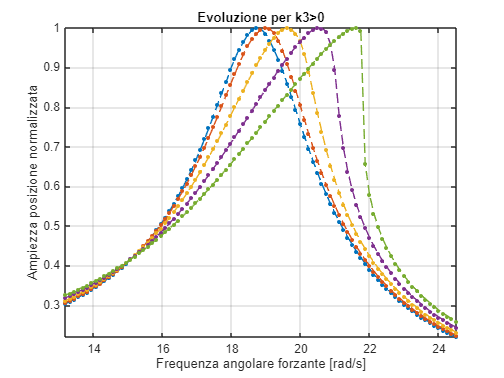

% Parametri
clearvars
f0     = 3;
omega0 = 2*pi*f0;
gamma  = 3;
A = 1;
omegaD = 2*pi*[2.1:0.02:3.9]; % Range di frequenze della forzante
k3 = [0:200:800]; % Range del termine di Duffing
t0     = 0;
durata = 20;
x0     = 0;
v0     = 0; % Cambiamo anche le condizioni iniziali e partiamo
% con un oscillatore fermo in posizione x = 0

figure(6);
for jk=1:length(k3)
    for j=1:length(omegaD)
        % Soluzione numerica
        ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma*xv(2)-k3(jk)^2*xv(1).^3+A*sin(omegaD(j)*t)];
        % 2. Soluzione numerica usando ode45
        [tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
        xx = xv(:,1);
        vv = xv(:,2);
        % Valutiamo l'ampiezza della posizione negli ultimi 150 punti della
        % scala temporale
        Amp(j) = max(xx(end-150:end)) - min(xx(end-150:end));
    end

    % Plot del risultato
    plot(omegaD,Amp/max(Amp),'--.','MarkerSize',10);
    hold on
    grid on;
    axis tight
    xlabel('Frequenza angolare forzante [rad/s]');
    ylabel('Ampiezza posizione normalizzata');
    title('Evoluzione per k3>0')
end

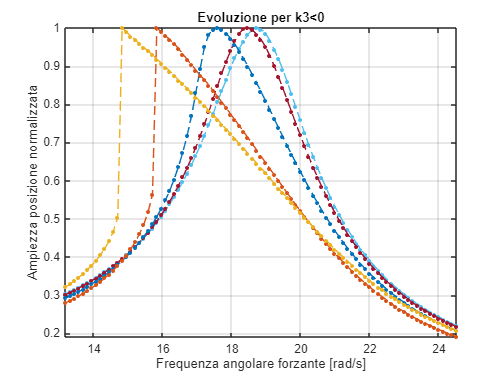

% Parametri
clearvars
f0     = 3;
omega0 = 2*pi*f0;
gamma  = 3;
A = 1;
omegaD = 2*pi*[2.1:0.02:3.9]; % Range di frequenze della forzante
k3 = [0:200:800]; % Range del termine di Duffing
t0     = 0;
durata = 20;
x0     = 0;
v0     = 0; % Cambiamo anche le condizioni iniziali e partiamo
% con un oscillatore fermo in posizione x = 0

figure(7);
for jk=1:length(k3)
    for j=1:length(omegaD)
        % Soluzione numerica
        ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma*xv(2)+k3(jk)^2*xv(1).^3+A*sin(omegaD(j)*t)];
        % 2. Soluzione numerica usando ode45
        [tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
        xx = xv(:,1);
        vv = xv(:,2);
        % Valutiamo l'ampiezza della posizione negli ultimi 150 punti della
        % scala temporale
        Amp(j) = max(xx(end-150:end)) - min(xx(end-150:end));
    end

    % Plot del risultato
    plot(omegaD,Amp/max(Amp),'--.','MarkerSize',10);
    hold on
    grid on;
    axis tight
    xlabel('Frequenza angolare forzante [rad/s]');
    ylabel('Ampiezza posizione normalizzata');
    title('Evoluzione per k3<0')
end

Come possiamo vedere dalle curve, il termine di Duffing inizialmente sposta la frequenza naturale dell'oscillatore verso il blu se $k_{3\;}$è positivo e verso il rosso se è negativo. Essendo la dinamica dell'oscillatore di Duffing molto comune nel contesto degli oscillatori meccanici si parla di *hardening *nel primo caso e di *softening* nel secondo, immaginando una possibile molla che diventa più rigida o più soffice rispettivamente nei due casi.

E' importante notare come le soluzioni evolvano da un regime **monostabile** ad un regime **bistabile. **Le chiare discontinuià delle curve equivalgono al "salto" del sistema da una soluzione stabile ad un'altra. E' significativo come la soluzione scelta dipenda dalle condizione iniziali, risultando in fenomeni di **isteresi** in funzione della direzione della "spazzata" della forzante.

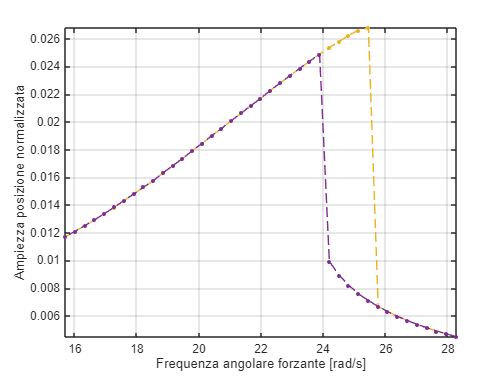

% Parametri
clearvars
f0     = 3;
omega0 = 2*pi*f0;
gamma  = 3;
A = 1;
omegaD = 2*pi*[2.5:0.05:4.5]; % Range di frequenze della forzante
k3 = 1500;
t0     = 0;
durata = 20;
x0     = 0;
v0     = 0; % Cambiamo anche le condizioni iniziali e partiamo
% con un oscillatore fermo in posizione x = 0

figure(8);
for js=1:2
    % Spazzata in "avanti" e all'"indietro"
    if js==2
        omegaD=flip(omegaD);
    end
    for j=1:length(omegaD)
        % Soluzione numerica
        ff = @(t,xv)[xv(2);-omega0^2*xv(1)-gamma*xv(2)-k3^2*xv(1).^3+A*sin(omegaD(j)*t)];
        % 2. Soluzione numerica usando ode45
        [tt xv] = ode45(ff,t0+[0 durata],[x0 v0]);
        xx = xv(:,1);
        vv = xv(:,2);
        % condizioni iniziali da soluzione precedente
        x0 = xx(end);
        y0 = vv(end);
        % Valutiamo l'ampiezza della posizione negli ultimi 150 punti della
        % scala temporale
        Amp(j) = max(xx(end-150:end)) - min(xx(end-150:end));
    end
    plot(omegaD,Amp,'--.','MarkerSize',10);
    hold on
    grid on;
    axis tight
    xlabel('Frequenza angolare forzante [rad/s]');
    ylabel('Ampiezza posizione normalizzata');
end